Case 3: Use simulated stock price data to verify Gamma Hedging

The first step specifies the parameters used simulate simulated stock price:

1) s0 is the initial price of stock

2) mu is the drift rate

2) sigma it the volatility

4) t_all is the total time

5) dt is the unit of time

6) s_n is the stock price array

7) t_n is the time array

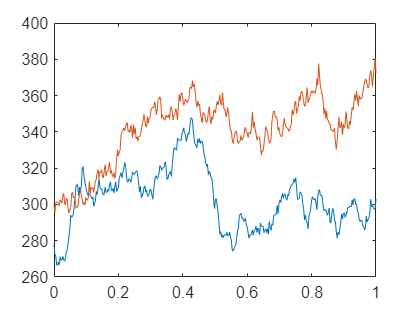

format compact;
%underlying stock for portfolio
s0=278;
mu=0.1;
sigma=0.2;
t_all=1;
dt=1/365;
rng(12344)  % set seed for regenerate
[s_n, t_n]=generate_stock_price1(s0, mu, sigma, t_all, dt);

%underlying stock for traded option
s0=300;
mu=0.1;
sigma=0.2;
t_all=1;
dt=1/365;
rng(124)  % set seed for regenerate
[s_n_trade, t_n_trade]=generate_stock_price1(s0, mu, sigma, t_all, dt);

A for loop for gamma hedging in 20 weeks, hedging daily

Delta_old=0;
Gamma_old=0;
cost=0;
traded_old=0;
stock_old=0;
i=1;
while i<=140
    %% Step 1: Compute total gamma and delta for portfolio
    DataMatrix = [s_n(i)  300  0.38356  0.2   0        % Call
              s_n(i)  270  0.38356  0.2   0        % Put
              s_n(i)  290  0.38356  0.2  0]  ;         % Call  
    RiskFreeRate = 0.0025; % 0.25%, consistent with real market data
    
    % assign each column of DataMatrix to a column vector whose name reflects 
    % the type of financial data in the column.
    StockPrice   = DataMatrix(:,1);
    StrikePrice  = DataMatrix(:,2);
    ExpiryTime   = DataMatrix(:,3);
    Volatility   = DataMatrix(:,4);
    DividendRate = DataMatrix(:,5);
    
    % use BSM price model in the financial toolbox here to compute call 
    % and put prices, gammas and deltas
    [CallPrices, PutPrices] = blsprice(StockPrice, StrikePrice,... 
    RiskFreeRate, ExpiryTime, Volatility, DividendRate);

    [CallDeltas, PutDeltas] = blsdelta(StockPrice,... 
    StrikePrice, RiskFreeRate, ExpiryTime, Volatility,... 
    DividendRate);

    Gammas = blsgamma(StockPrice, StrikePrice, RiskFreeRate,...
                  ExpiryTime, Volatility , DividendRate)';
              
    Prices = [CallPrices(1) PutPrices(2) CallPrices(3)]; 
    Deltas = [CallDeltas(1) PutDeltas(2) CallDeltas(3)]; 
    %total gamma of the portfolio, with 1,000 of each of the three options
    Gamma_total=sum(Gammas)*1000; 
    Delta_total=sum(Deltas)*1000;
    
    %keep track of changes in delta and gamma every day
    Delta_change=Delta_total-Delta_old;
    Delta_old=Delta_total;
    Gamma_change=Gamma_total-Gamma_old;
    Gamma_old=Gamma_total;
    %% Step 2: Compute gamma and delta for traded option
    tradedMatrix = [s_n_trade(i)  310  0.38356  0.2   0];      % Call
    % Do similar things as Step 1
    StockPrice_T   = tradedMatrix(:,1);
    StrikePrice_T  = tradedMatrix(:,2);
    ExpiryTime_T   = tradedMatrix(:,3);
    Volatility_T   = tradedMatrix(:,4);
    DividendRate_T = tradedMatrix(:,5);

    [CallPrices_T, PutPrices_T] = blsprice(StockPrice_T, StrikePrice_T,... 
    RiskFreeRate, ExpiryTime_T, Volatility_T, DividendRate_T);

    [CallDeltas_T, PutDeltas_T] = blsdelta(StockPrice_T,... 
    StrikePrice_T, RiskFreeRate, ExpiryTime_T, Volatility_T,... 
    DividendRate_T);

    Gamma_T = blsgamma(StockPrice_T, StrikePrice_T, RiskFreeRate,...
                  ExpiryTime_T, Volatility_T, DividendRate_T)';
              
    Price_T = CallPrices_T;
    Delta_T = CallDeltas_T;
    
    %% Step 3: gamma hedging the portfolio using traded option and underlying stock of the portfolio
    %get gamma neutral first
    traded_quantity=-Gamma_change/Gamma_T; %quantity we should long in traded option
    traded_change=traded_quantity-traded_old;
    traded_old=traded_quantity;
    %then get delta neutral
    stock_quantity=-(Delta_change+traded_quantity*Delta_T); %quantity we should long in underlying stock of the treded option
    stock_change=stock_quantity-stock_old;
    stock_old=stock_quantity;
    %compute total costs
    cost=cost+Price_T*traded_change+stock_change*s_n(i); %s_n(i) is the current stock price
    i=i+1;
end
cost

cost = 2.8904e+04

The stock price at maturity date is $329.8267, which makes it strongly in the money for both call options in the portfolio, and strongly out of money for the put option in the portfolio. Therefore, the institution receives (1000*300+1000*290)=$590,000 since the buyer will exercise call options in the portfolio. The expenditure we used for Gamma hedging is $28,904. With the initial payment of $30,000, the institution gets a profit of $591,096. This is a big amount of profit, which is rare in the real market since the probability of the stock price to increase by about 20% in 20 weeks is low.

Below is the function that generates the simulated stock price

function [s_n, t_n] = generate_stock_price1(s0, mu, sigma, t_all, dt)
t_n = [0:dt:t_all]';   % get the time array

BM_n = [0 dt^0.5*cumsum(randn(1,t_all/dt))]';    %construct a standard brownian motion

s_n = s0 * exp((mu-0.5*sigma^2) * t_n+sigma * BM_n);  %construct the stock price 
plot(t_n,s_n), hold on

end